## Goal

It's difficult to build a generalized transfer function that assumes any signal can be applied to any terminal. I think that S-parameters are likely the best way to do this, but I don't know much about them at the moment. So I'm going to build a transfer function for the full dendrite, assuming that a signal is applied to all of the terminations.

## Algorithm Overview

This approach is based on finding the parallel impedance of termination nodes. So it will cycle through all of the terminations, find the ones that are in parallel (I'll call those sister nodes), and then find their equivalent impedance. It will then add their impedance to the impedance of the parent nodes. The dendrite can then be simplified to consider just a single branch representing the equivalent impedance of all three components.

Any Continuation nodes (two branches in series) will also be added and simplified to a single equivalent impedance.

This algorithm will run repeatedly until the dendrite is just two nodes, n1 (Gnd) and n2 (Vs).

I initially considered this a recursive algorithm, but doesn't need to be. That would consume a lot of memory for large complex dendrites. So it will just loop repeatedly until the 2-node dendrite is found, or some error conditions are met.

## Network Analysis

The calculations will be done using 2-Port Networks. I watched a lot of videos from [Neso Academy on Youtube](https://www.youtube.com/watch?v=pn777Ya0OHk&list=PLBlnK6fEyqRjQZj_QXvH8sp1lOWtjQCtT). I learned about the topic from the book Electronics and Circuit Analysis Using MATLAB by Attia. I saved a copy on the drive. It's about 20 years old, so it doesn't have the most current tools, but it has good techniques.

I also looked into using the Circuit objects of the MATLAB RF Toolbox. It's a really powerful tool, but I'm not totally sure how to interpret the results, which are in the form of S-Parameters. This is probably the best long term solution, as it can find the transfer functions between any desired node.

The parameters that I'll be using are called Transmission Parameters, or ABCD Parameters, depending on the source (there may be a difference but I can't figure out what it is). They represent the relationship between the input and output voltages and currents of a generalized 2-port network. The following screenshots are taken from the Attia book, Chapter 7

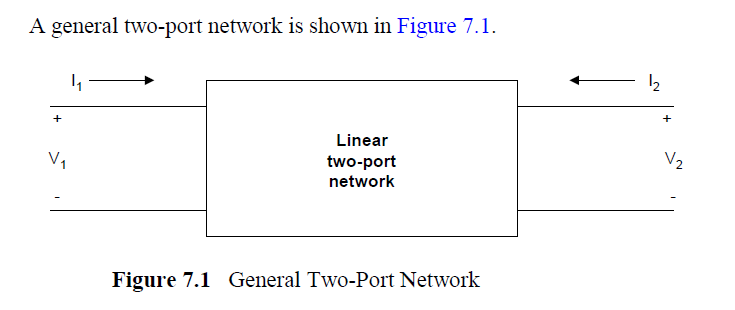

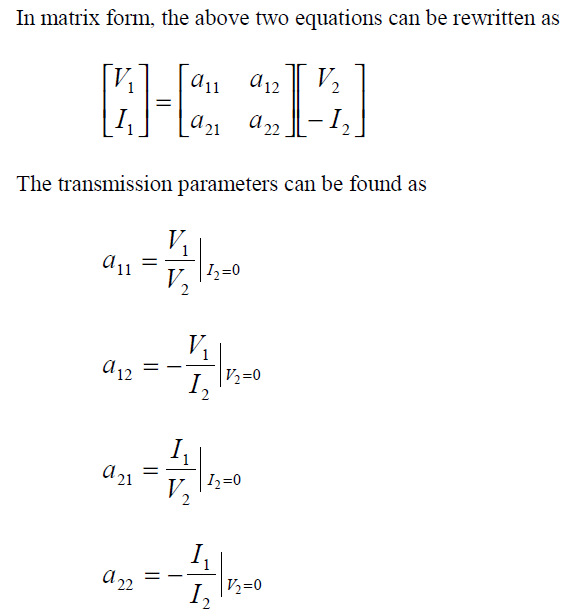

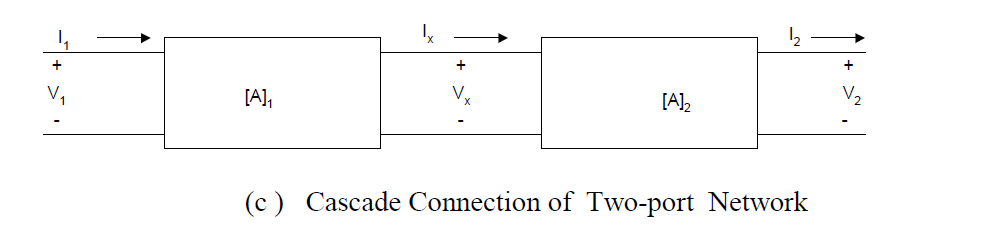

There are several types of similar parameters. The advantage of T-Parameters is that when you cascade networks, as shown above, the resulting network can be represented by multiplying the matrices for each network.

For a unit cell of a resistor between nodes, and a shunt capacitor to ground, the following matrix gives the T-parameters.

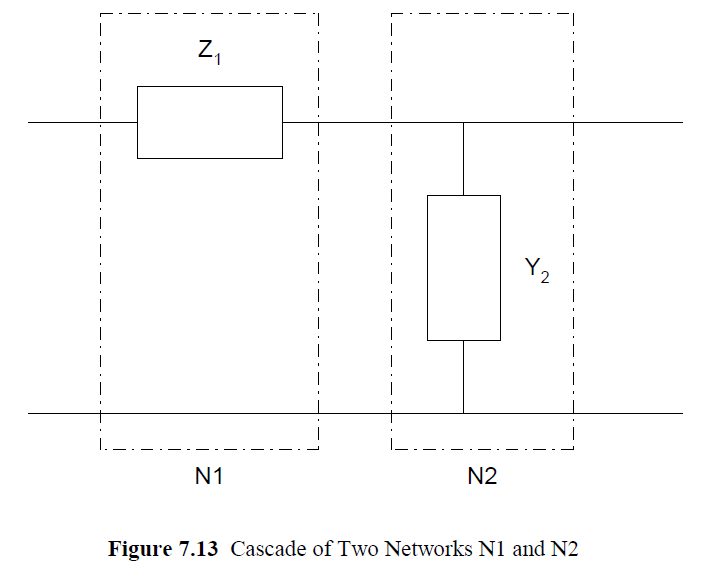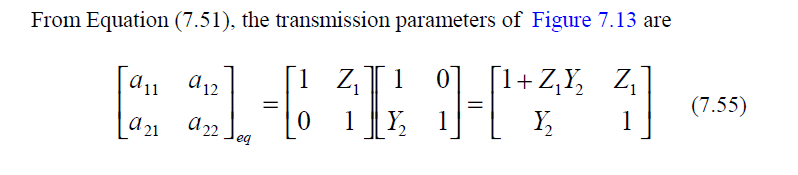

## Parameter Conversions

In order to combine parallel elements, it seems like the best approach is to convert to Y-parameters (admittance). The Y matrices of parallel networks can be added. To convert between ABCD, Y, and Z networks, use the following conversions from "Conversions between S, Z, Y, H, ABCD, and T parameters which are valid for complex source and load impedances" (D.A. Frickey, IEEE, saved on drive). Note that Y is just the inverse of Z.

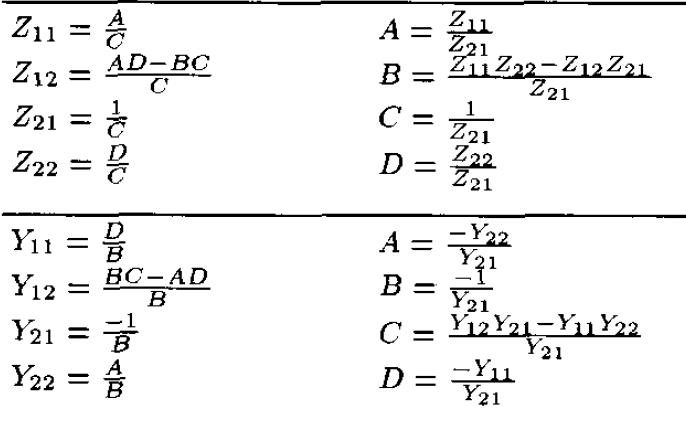

In order to simply this, I'll just write a function to take care of the conversions. Matlab already has functions with the same names but lowercase letters. Unfortunately, these handle complex numbers and not transfer functions. So they compute the parameters for a single frequency instead of full TFs. Here's a demo of the functions. I used these values because they match some that were used in an example video I found on Youtube. The value of Ytest should equal the value of Y.

Y = [1.5 -0.5; -0.5, 2.5]

Y =     1.5000   -0.5000
   -0.5000    2.5000


ABCD = Y2ABCD(Y)


ABCD =
 
  From input 1 to output...
   1:  5
 
   2:  7
 
  From input 2 to output...
   1:  2
 
   2:  3
 
Static gain.



Ytest = ABCD2Y(ABCD)


Ytest =
 
  From input 1 to output...
   1:  1.5
 
   2:  -0.5
 
  From input 2 to output...
   1:  -0.5
 
   2:  2.5
 
Static gain.



***The function works, but for some reason it won't work when I give it transfer function. Not sure why, because when I do each of the steps separately, it works fine. So I'll just skip that part. Maybe I'll fix it later.

***I fixed it. The problem was when I created a matrix to fill in with the results. I was just using zeros(2), but that created a matrix of doubles, which cannot be replaced with TFs. I fixed it by doing s*ones(2), instead. So they start off as TFs.

At the end of the network, the V1+ and V1- would be equal, which allows you to solve for the impedance of the full network. By the definition of the parameters:


$$V_1 ={\mathrm{AV}}_2 -{\mathrm{BI}}_2$$


So if V_1 is 0:


$${\textrm{AV}}_2 ={\textrm{BI}}_2$$


The Short-Circuit Output Impedance is:


$$Z_{\mathrm{os}} =\frac{V_2 }{I_2 }=\frac{B}{A}$$


## Start with a dendrite

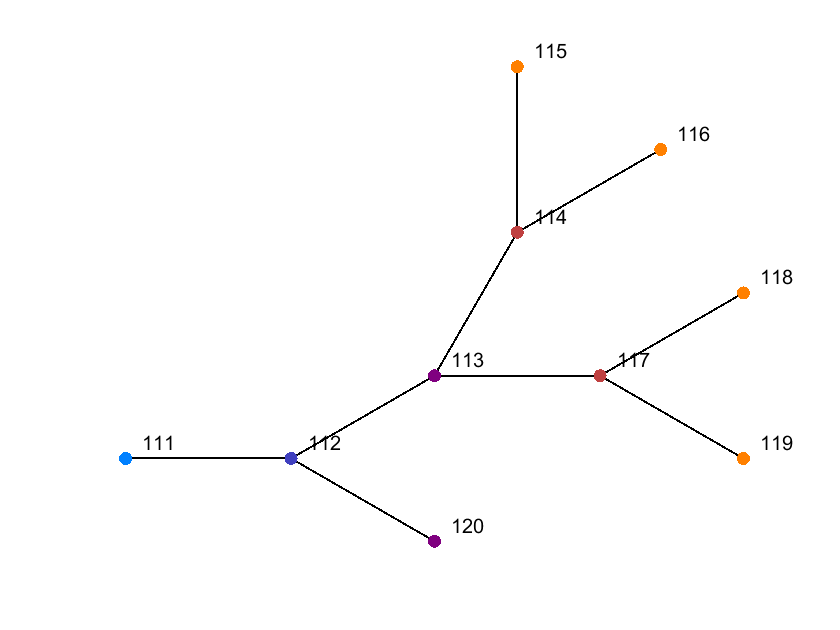

Current plot held


clear
load dendrites10.mat;
n = 16;
d1 = dendrite(trees{n}.dA, trees{n}.X, trees{n}.Y, []);

d1.plot(d1.branchOrder, 'n');

## Algorithm Code

Create some matrices and vectors to store desired info. The dA and coordinate vectors will be chopped up. So I need a copy that won't affect the original dendrite.

s = tf('s');
impedanceTotal = cell(d1.nodes,1);

dA = d1.dA;
BCT = d1.BCT;
X = d1.X;
Y = d1.Y;

R = d1.R;
C = zeros(size(R));
BO = d1.branchOrder;

for i = 2:length(C)
    C(i) = (100e-6)*0.5^(BO(i)-1);
end

errorCheck = false;

Pre load each of the nodes with an ABCD matrix.

for i = 2:10
    impedanceTotal{i} = s*ones(2);
    impedanceTotal{i}(1,1) = 1+R(i)*C(i)*s;
    impedanceTotal{i}(1,2) = R(i);
    impedanceTotal{i}(2,1) = C(i)*s;
    impedanceTotal{i}(2,2) = 1;
end

impedanceEq = impedanceTotal;

Start the loop. Use a while loop.

while(length(X)>2 && errorCheck == false)
    terminations = find(BCT==0);

    
    for i=1:length(terminations)
        parent = find(dA(terminations(i),:));
        
        if(BCT(parent)==1)
            % Find the cascaded equivalent matrix by multiplying the ABCD matrices
            impedanceEq{parent} = minreal(impedanceEq{parent}*impedanceEq{terminations(i)});
            
            % Now clean up the matrices and vectors so we know that these networks were combined.
            X(terminations(i)) = [];
            Y(terminations(i)) = [];
            
            dA(terminations(i),:) =[];
            dA(:,terminations(i)) =[];
            BCT = ones(1,length(X))*dA;
            break
        elseif(BCT(parent)==2)
            % If the parent is a branch.
            % Find the sister node.
            sister = find(dA(:,parent));
            termRepeat = find(sister==terminations(i));
            sister(termRepeat) = [];

            % Check if sister node is also a termination
            if(BCT(sister) == 0)
                tCurrent = terminations(i);
                % If the sister nodes are each terminations, then they can be combined by adding their Y matrices
                ySum = minreal(ABCD2Y(impedanceEq{terminations(i)}) + ABCD2Y(impedanceEq{sister}));
                
                % Then they can be merged with the parent node by multiplying the ABCD matrices;
                impedanceEq{parent} = minreal(impedanceEq{parent}*Y2ABCD(ySum));
                
                
                % Now clean up.
                X(terminations(i)) = [];
                Y(terminations(i)) = [];
                
                dA(terminations(i),:) =[];
                dA(:,terminations(i)) =[];
                
                
                X(sister-1) = [];
                Y(sister-1) = [];
                
                dA(sister-1,:) =[];
                dA(:,sister-1) =[];
                
                BCT = ones(1,length(X))*dA;
                
                break;
                %{
                % Also remove the sister from the terminations list, since it's done
                
                
                % I also need to adjust the value of any entry in terminations that was higher than the removed ones
                greaterThanSis = find(terminations>sister);
                terminations(greaterThanSis) = terminations(greaterThanSis)-1;
                
                greaterThanThis = find(terminations>tCurrent);
                terminations(greaterThanThis) = terminations(greaterThanThis)-1;
                terminations(find(terminations)==sister) = []
                %}
            end
        end
    end
end

Zosc = minreal(impedanceEq{2}(1,2)/impedanceEq{2}(1,1))


Zosc =
 
                                                                                                                
  1.143e04 s^98 + 3.182e08 s^97 + 4.379e12 s^96 + 3.969e16 s^95 + 2.667e20 s^94 + 1.416e24 s^93 + 6.19e27 s^92  
                                                                                                                
          + 2.291e31 s^91 + 7.329e34 s^90 + 2.058e38 s^89 + 5.135e41 s^88 + 1.15e45 s^87 + 2.331e48 s^86        
                                                                                                                
          + 4.305e51 s^85 + 7.285e54 s^84 + 1.135e58 s^83 + 1.637e61 s^82 + 2.191e64 s^81 + 2.732e67 s^80       
                                                                                                                
          + 3.183e70 s^79 + 3.473e73 s^78 + 3.559e76 s^77 + 3.431e79 s^76 + 3.118e82 s^75 + 2.676e85 s^74       
                                                                                      


bandwidth(Zosc)/(2*pi)      

ans = 2.4437

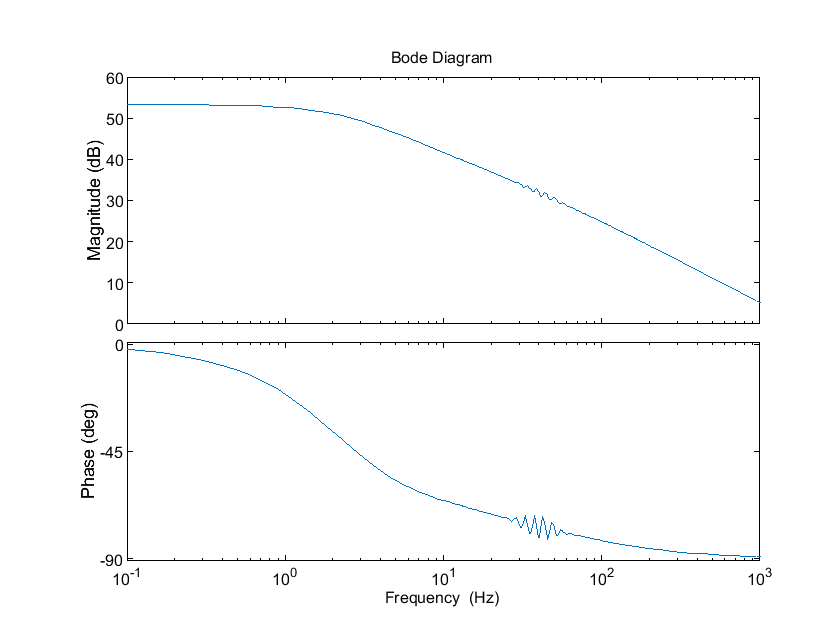


opts = bodeoptions;
opts.FreqUnits = 'Hz';
bodeplot(Zosc, opts)

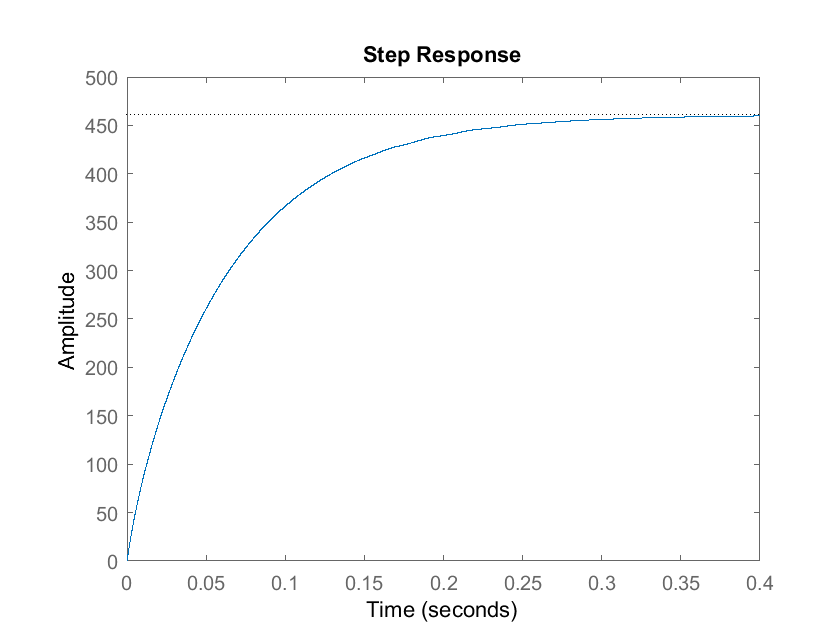

step(Zosc)